# Introduction to MATLAB

**Objectives**

By the end of this lesson, students will:

- Understand the MATLAB environment and basic syntax

- Practice using variables, vectors, and matrices

- Learn how to create and interpret plots

- Explore logical indexing and basic programming constructs (if, for, while)

- Use help and documentation effectively

**Why This Matters**

MATLAB is widely used in biomedical engineering for analyzing signals, simulating systems, and visualizing data. Getting comfortable with its environment is the first step toward building your own analytical tools, from heart rate estimators to prosthetic control systems. These lessons won't be only helpful to use MATLAB nut to have a broad knowledge about programming logic.

## 1. Getting Started with MATLAB

Launch MATLAB and explore the interface:

- Current Folder

- Command Window

- Editor

- Workspace

**Activity**

Type

and,

in the Command Window. Describe what each command does.

- `help clc`: 

- `help clear`: 

- `help who`: 

What differences do you observe between the Command Window and the Editor?

## 2. Variables and Data Types

Create variables and explore data types:

a = 5;
b = 3.2;
name = 'Daniel';
is_student = true;

Check class and size using:

class(a)
class(b)
class(name)
class(is_student)
size(name)
whos

**Practice**

Create a variable for your name, your age, and whether you're a MATLAB novice. Display each variable's class.

% Write your code here
% To display values use the built-in function disp




### 2.1. Numeric Types

#### 2.1.1. **Floating-Point Numbers**

Range: –3.4 × 1038 and 3.4 × 1038

Representation:


$$x={-1}^s \cdot \left(1+f\right)\cdot 2^e$$


Where,

$s$ is for the sign of the number

$f$ is the fraction, or *mantissa*, which satisfies $0\le f<1$.

$e$ is the exponent

- `single` (32-bit)

- `double` (64-bit) [default]

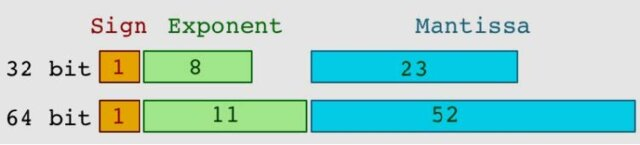 Image taken from: Tarigan, Jos & Zamzami, Elviawaty & Laurent Ginting, Cindy. (2018). Performance Analysis of BigDecimal Arithmetic Operation in Java. Journal of ICT Research and Applications. 12. 267. 10.5614/itbj.ict.res.appl.2018.12.3.5. 

**Activity:** Find the largest and smallest positive values that can be represented with the `double` data type by using the `realmax` and `realmin` functions, respectively.

#### 2.1.2. Integers

#### 2.1.3. Complex


$$\mathrm{var}\_\mathrm{name}=\mathbb{R}e+\mathbb{I}m$$


Example: 

Can be created by using the `complex` function.

x = 2 + 3i
y = complex(5, 8)
real(y)
imag(y)

#### 2.1.4. Infinity

Represented with the function `Inf`

Examples of when you get Inf

x = 1/0
y = 1.e1000
z = exp(1000)
w = log(0)

#### 2.1.5. NaN

Values that are not real or complex numbers

`NaN = `Not a Number

x = 0/0

x = NaN

### 2.2. Characters and Strings

### 2.3. Boolean

true (logical 1)

false (logical 0)

### 2.4. Tables

### 2.5. Structures

MyStruct = struct;
MyStruct.SecondStruct.a = 1;
MyStruct.SecondStruct.b = 2;
MyStruct.SecondStruct.c = "string!!!";
MyStruct.Other = "Hello World";

## 3. Vectors and Matrices

Define row and column vectors:

x = [1 2 3];       % Row
y = [1; 2; 3];     % Column

Access elements: 

x(2)
y(3)

Use functions: 

length(x)
size(y)
mean(x)
std(x)

**Exercise:**

Create a 3x3 matrix and:

- Extract the second row

- Calculate the determinant

- Add 2 to every element using vectorized code

## 4. Plotting Basics

Use plot(x, y) for 2D plots:

x = 0:0.1:2*pi;
y = sin(x);

plot(x, y)
xlabel('x'); ylabel('sin(x)');
title('Sine Wave');

Customize with grid on, axis, legend, hold on

**Challenge:**

Plot both sin(x) and cos(x) on the same figure. Label them and add a legend.

## 5. Logical Indexing and Conditions

Use logical operators: >, <, ==, ~, &, |

Filter arrays:

A = [3 5 7 9 11];
A(A > 6)

### 5.1. Conditional statements

#### 5.1.1. `if, ifelse, else`

if mod(x,2) == 0
    disp('Even')
else
    disp('Odd')
end

#### 5.1.2. `switch, case, otherwise`

switch class(x)
    case 'string'
        disp("This is a string")
    case 'double'
        disp("This is a double")
    case 'table'
        disp("This is a table")
    otherwise
        disp("Nothing")
end

**Try This:** Write a script that takes a number and says whether it's positive, negative, or zero.6.

### 5.2. Loops

#### 5.2.1. `for`

for i = 1:5
    disp(i^2)
end

#### 5.2.2. `while`

i = 1;
while i <= 5
    disp(i^2)
    i = i + 1;
end

**Practice Task: **Write a loop that sums all numbers from 1 to 100.

## 6. Using Help and Documentation

Try `help`, `doc`, or clicking on functions in the Editor

Explore the Live Editor Tasks

**Exploration:** Find and summarize what the function `linspace` does. Create a plot using it.

## Summary

You learned how to define and manipulate variables, plot data, apply logical indexing, and use programming constructs.

You explored the MATLAB interface and documentation tools.

## Revision History

## References

- MathWorks. *MATLAB 2025a Documentation*. The MathWorks, Inc. Available: [https://www.mathworks.com/help/matlab/](https://www.mathworks.com/help/matlab/)